## Лабораторна робота 2

## **1. **Завантажити тестові зображення

moon = imread('moon.tif');
cameraman = imread('cameraman.tif');
peppers = imread('peppers.png');

## **2.** Відобразити вихідні зображення

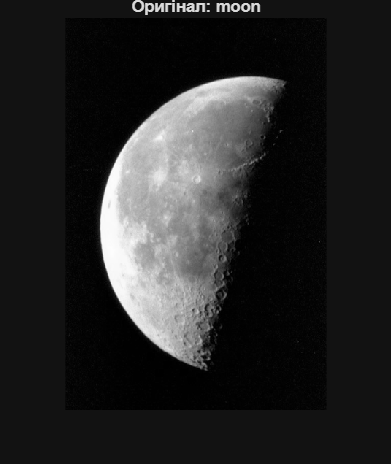

figure, imshow(moon), title('Оригінал: moon');

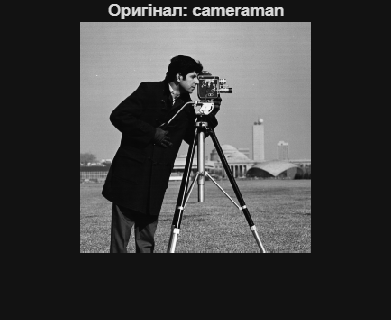

figure, imshow(cameraman), title('Оригінал: cameraman');

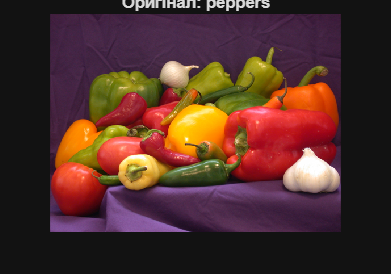

figure, imshow(peppers), title('Оригінал: peppers');

## **3.** Додати шум

cameraman_noise_gauss = imnoise(cameraman, 'gaussian', 0, 0.01);
cameraman_noise_sp = imnoise(cameraman, 'salt & pepper', 0.02);
peppers_noise_gauss2 = imnoise(peppers, 'gaussian', 0, 0.01);
peppers_noise_sp2 = imnoise(peppers, 'salt & pepper', 0.02);
moon_noise_gauss3 = imnoise(moon, 'gaussian', 0, 0.01);
moon_noise_sp3 = imnoise(moon, 'salt & pepper', 0.02);

## **4.** Відобразити зашумлені зображення

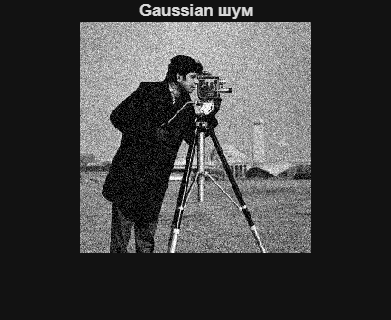

figure, imshow(cameraman_noise_gauss), title('Gaussian шум');

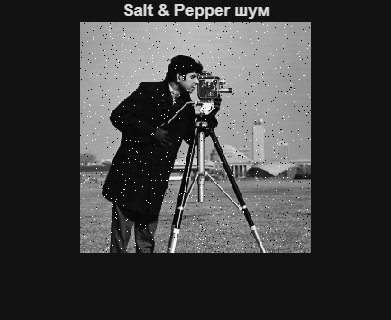

figure, imshow(cameraman_noise_sp), title('Salt & Pepper шум');

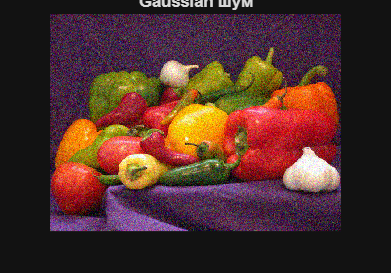

figure, imshow(peppers_noise_gauss2), title('Gaussian шум');

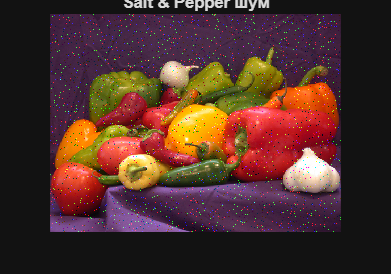

figure, imshow(peppers_noise_sp2), title('Salt & Pepper шум');

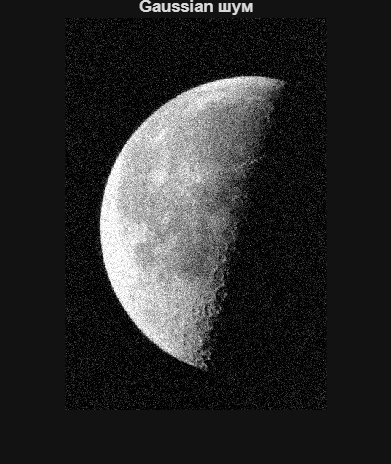

figure, imshow(moon_noise_gauss3), title('Gaussian шум');

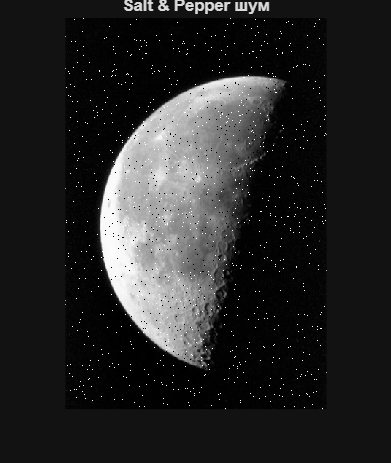

figure, imshow(moon_noise_sp3), title('Salt & Pepper шум');

## **5.** Лінійна фільтрація


lowpass_filter = fspecial('gaussian', [5 5], 1);
highpass_filter = fspecial('unsharp');

img_lowpass = imfilter(cameraman, lowpass_filter);
img_highpass = imfilter(cameraman, highpass_filter);

img_lowpass2 = imfilter(peppers, lowpass_filter);
img_highpass2 = imfilter(peppers, highpass_filter);

img_lowpass3 = imfilter(moon, lowpass_filter);
img_highpass3 = imfilter(moon, highpass_filter);

## **6.** Відобразити результати

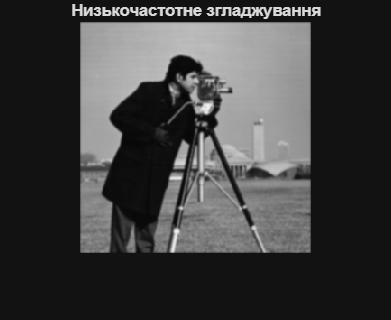

figure, imshow(img_lowpass), title('Низькочастотне згладжування');

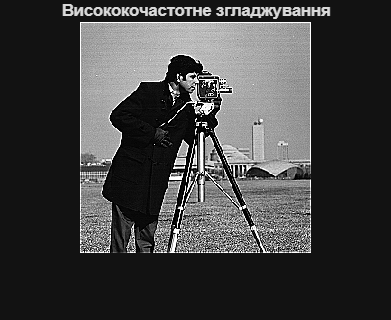

figure, imshow(img_highpass), title('Висококочастотне згладжування');

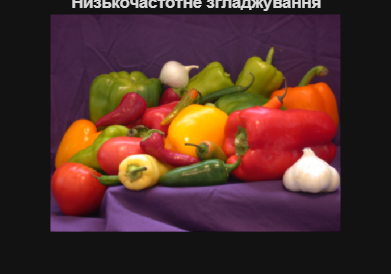


figure, imshow(img_lowpass2), title('Низькочастотне згладжування');

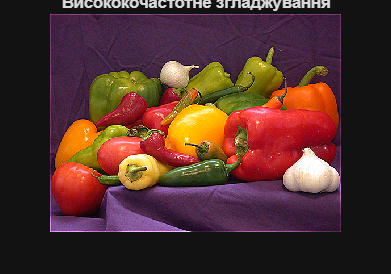

figure, imshow(img_highpass2), title('Висококочастотне згладжування');

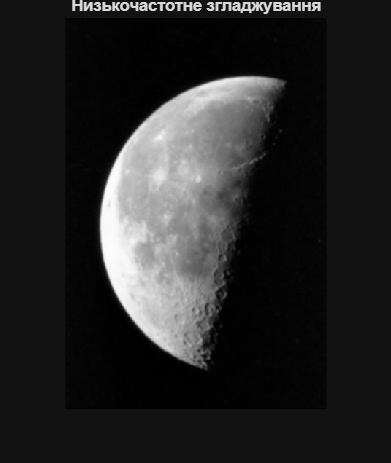



figure, imshow(img_lowpass3), title('Низькочастотне згладжування');

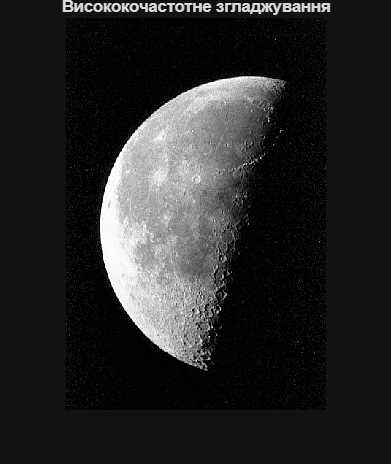

figure, imshow(img_highpass3), title('Висококочастотне згладжування');

## **7.** Фільтрація зашумлених зображень

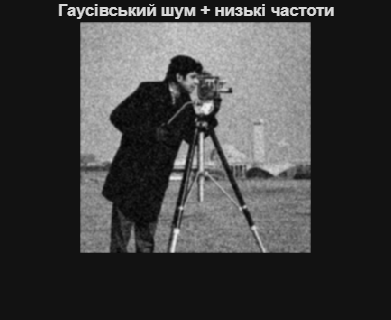

img_gauss_filtered = imfilter(cameraman_noise_gauss, lowpass_filter);
img_sp_filtered = imfilter(cameraman_noise_sp, lowpass_filter);

img_gauss_filtered2 = imfilter(peppers_noise_gauss2, lowpass_filter);
img_sp_filtered2 = imfilter(peppers_noise_sp2, lowpass_filter);

img_gauss_filtered3 = imfilter(moon_noise_gauss3, lowpass_filter);
img_sp_filtered3 = imfilter(moon_noise_sp3, lowpass_filter);

figure, imshow(img_gauss_filtered), title('Гаусівський шум + низькі частоти');

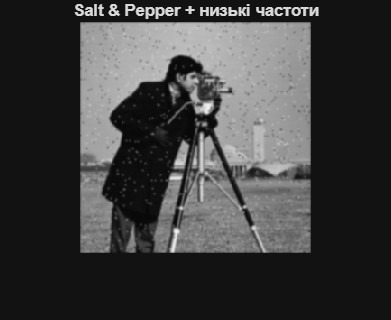

figure, imshow(img_sp_filtered), title('Salt & Pepper + низькі частоти');

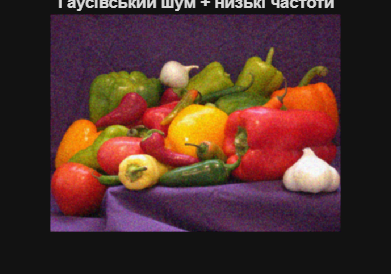



figure, imshow(img_gauss_filtered2), title('Гаусівський шум + низькі частоти');

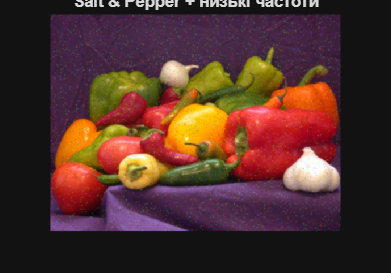

figure, imshow(img_sp_filtered2), title('Salt & Pepper + низькі частоти');

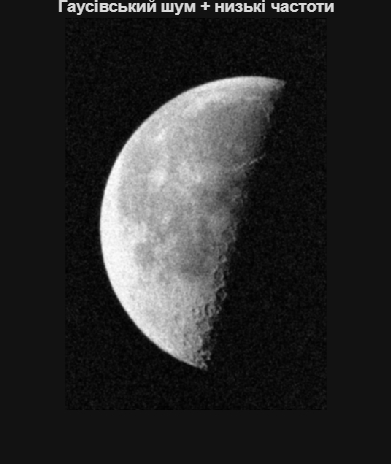



figure, imshow(img_gauss_filtered3), title('Гаусівський шум + низькі частоти');

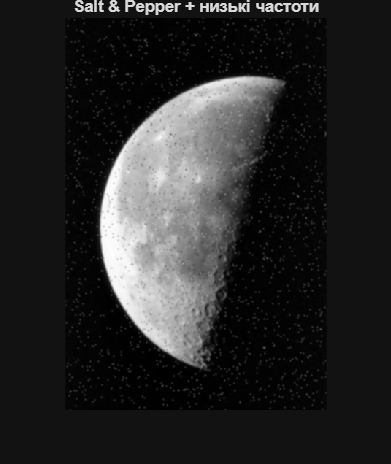

figure, imshow(img_sp_filtered3), title('Salt & Pepper + низькі частоти');

## **8.** Адаптивна вінерівська фільтрація

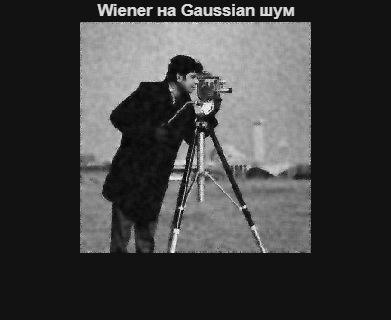

img_gauss_wiener = wiener2(cameraman_noise_gauss, [5 5]);
img_sp_wiener = wiener2(cameraman_noise_sp, [5 5]);
img_gauss_wiener2 = wiener2(rgb2gray(peppers_noise_gauss2), [5 5]);
img_sp_wiener2 = wiener2(rgb2gray(peppers_noise_sp2), [5 5]);
img_gauss_wiener3 = wiener2(moon_noise_gauss3, [5 5]);
img_sp_wiener3 = wiener2(moon_noise_sp3, [5 5]);


figure, imshow(img_gauss_wiener), title('Wiener на Gaussian шум');

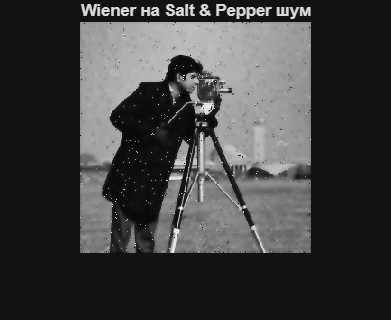

figure, imshow(img_sp_wiener), title('Wiener на Salt & Pepper шум');

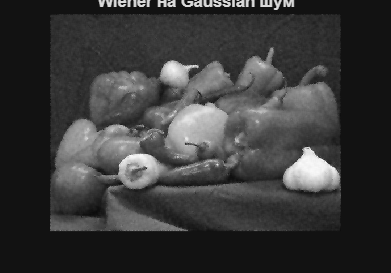

figure, imshow(img_gauss_wiener2), title('Wiener на Gaussian шум');

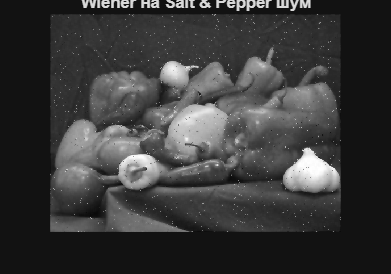

figure, imshow(img_sp_wiener2), title('Wiener на Salt & Pepper шум');

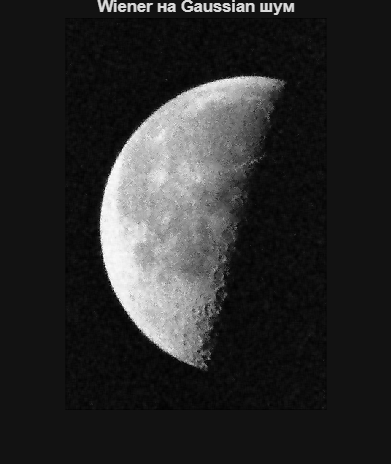

figure, imshow(img_gauss_wiener3), title('Wiener на Gaussian шум');

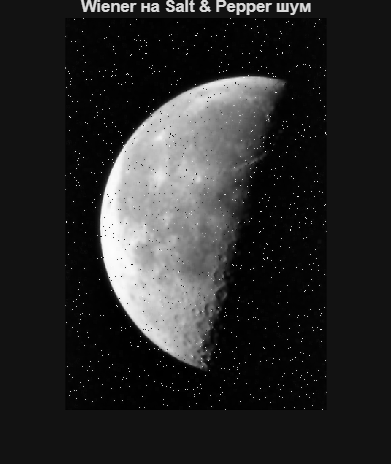

figure, imshow(img_sp_wiener3), title('Wiener на Salt & Pepper шум');

## **9.** Медіанна фільтрація

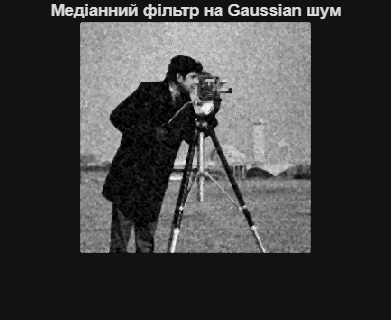

img_gauss_med = medfilt2(cameraman_noise_gauss);
img_sp_med = medfilt2(cameraman_noise_sp);
img_gauss_med2 = medfilt2(rgb2gray(peppers_noise_gauss2));
img_sp_med2 = medfilt2(rgb2gray(peppers_noise_sp2));
img_gauss_med3 = medfilt2(moon_noise_gauss3);
img_sp_med3 = medfilt2(moon_noise_sp3);

figure, imshow(img_gauss_med), title('Медіанний фільтр на Gaussian шум');

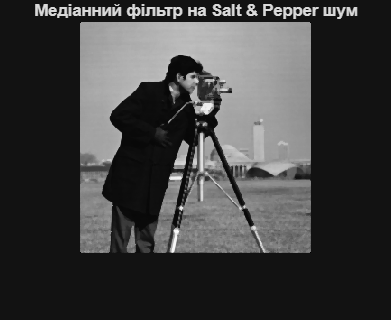

figure, imshow(img_sp_med), title('Медіанний фільтр на Salt & Pepper шум');

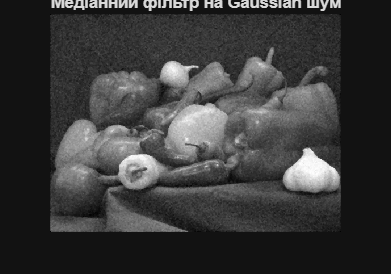

figure, imshow(img_gauss_med2), title('Медіанний фільтр на Gaussian шум');

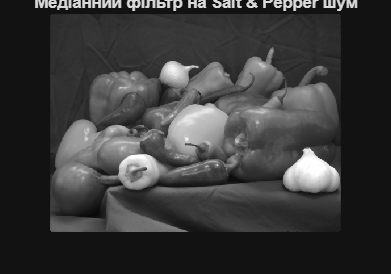

figure, imshow(img_sp_med2), title('Медіанний фільтр на Salt & Pepper шум');

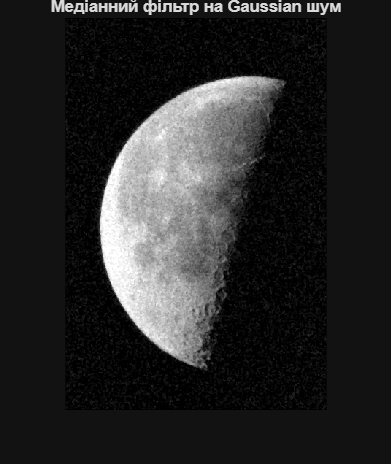

figure, imshow(img_gauss_med3), title('Медіанний фільтр на Gaussian шум');

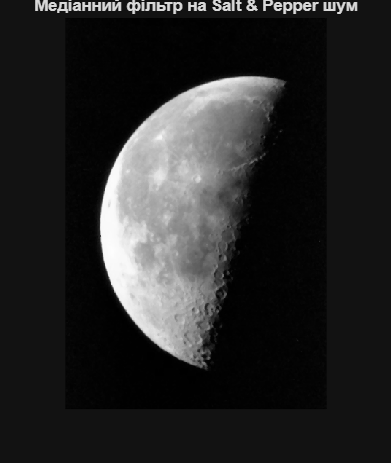

figure, imshow(img_sp_med3), title('Медіанний фільтр на Salt & Pepper шум');